cycles = 2:2:100;

TTNB = 360; % timeToNextBurst (us)
            %Parameters = [1,0.9,10,1];

clockPeriod = 4e-9;
waves = zeros(length(cycles),int32(TTNB*1e-6/clockPeriod));
for i = 1:length(cycles)
    wvfm = genWvfm([1,0.9,cycles(i),1]);
    waves(i,1:length(wvfm)) = wvfm;
end



onTime = sum(abs(waves),2).*4e-3; % us
offTime = TTNB-onTime;
dutyCycle = onTime./TTNB; % including non-pulse time
V = 1.6:1:2*96;
I = 0.5;
P = I.*V; % watts amplitude
transmitPower = dutyCycle*P; % average watts per transmit 


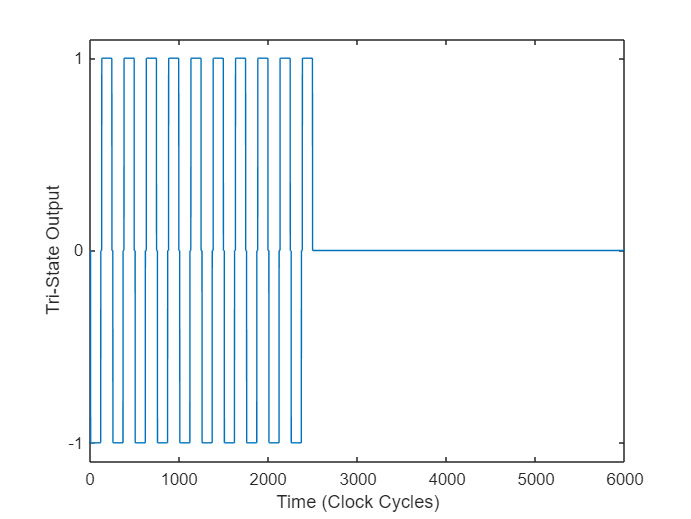


plot(waves(10,1:6000))
xlabel('Time (Clock Cycles)')
ylabel("Tri-State Output")
yticks([-1,0,1])
ylim([-1.1,1.1])

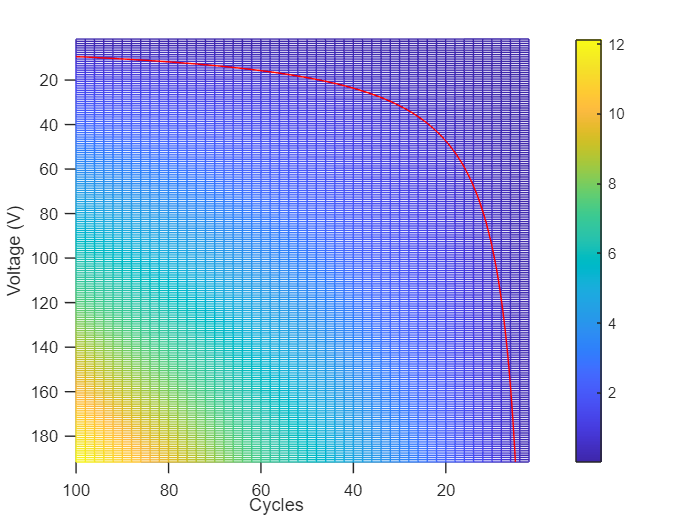


figure(1)
plt = meshc(V,cycles,transmitPower);
plt(2).LevelList = 0.6;
plt(2).EdgeColor = 'r';
ylabel('Cycles')
xlabel('Voltage (V)')
colorbar()
view([-89.99 -90.00])


W = 0.9;
N = 10;
Voltage = 50;
state = [Voltage,W,N,TTNB]

state =    50.0000    0.9000   10.0000  360.0000


[Voltage,W,N,TTNB] = fixPower(10,'V',state,0.63,genWvfm([1,W,N,1]))

transmitPower = 0.3167

k = 2.5200

kN = 2.8347

N = 28

dutyCycle = 0.0618

transmitPower = 0.3088

Voltage = 10

W = 1

N = 28

TTNB = 226.7787